clearvars; close all; clc;
addpath ("hydraulicLosses\")

addpath ("Motor\")

addpath ("pumpFunctions\")

addpath ("pumps\")

addpath ("initialData\")

***Batería comercial con potencia constante e intensidad variable***

***Descarga?? o ciclo completo?***

# Battery properties

[experiment, electrolite, electrode, manifold, frame, nCell, nStack, SoCmax] = initValues()

electrolite = struct with fields:
     mu: 0.004930000000000
    rho: 1354
      g: 9.810000000000000
     cv: 1.650000000000000


experiment = struct with fields:
     FF: 6
    SoC: [15×1 double]
      J: 0.080000000000000


electrolite = struct with fields:
     mu: 0.004930000000000
    rho: 1354
      g: 9.810000000000000
     cv: 1.650000000000000


electrode = struct with fields:
           df: 9.000000000000000e-06
    ePorosity: 0.900000000000000
        cteCK: 4.280000000000000
           We: 0.400000000000000
           Le: 0.400000000000000
           He: 0.003000000000000


manifold = struct with fields:
            W: 0.180000000000000
            H: 0.024000000000000
            L: 0.263000000000000
            e: 0.001500000000000
    hManifold: 0.460000000000000


frame = struct with fields:
         HchannelBetweenRibs: 1.000000000000000e-03
         WchannelBetweenRibs: 0.025000000000000
         LchannelBetweenRibs: 0.018000000000000
    numberOfHolesBetweenRibs: 6


nCell =     20


nStack =      4


SoCmax =    0.900000000000000


battery = initBatt(nStack, nCell, SoCmax) % nStacks, nCell, z_ini -> initial SoC

battery = struct with fields:
           r0: 0.108000000000000
           rn: 0
           rc: 0
            Q: 10000
        cells: 80
          ocv: [100×1 double]
          soc: [100×1 double]
       etaChg: 0.950000000000000
          z_k: 0.900000000000000
          v_k: 1.150387789572281e+02
        irn_k: 0
    vHistoric: []
    zHistoric: []
    pHistoric: []
    eHistoric: []
    iHistoric: []


- z_ini - SoC

## Current profile simulation

current = [-10, 10, 10, 10, -10];
for i = 1:length(current)
    battery = simStep(current(i),battery,1);
end


- Qué es current? [-10, 10, 10...] vector de qué?

## Power to desire SoC simulation

[battery, t] = CP(battery, 7000, 0.20) %Constant Power simulation % (battery, power, expectedSoC) 

battery = struct with fields:
           r0: 0.108000000000000
           rn: 0
           rc: 0
            Q: 10000
        cells: 80
          ocv: [100×1 double]
          soc: [100×1 double]
       etaChg: 0.950000000000000
          z_k: 0.199913427089309
          v_k: 94.835376839098643
        irn_k: 73.811163746827276
    vHistoric: [1.139587789572281e+02 1.161177166068920e+02 1.161187258397113e+02 1.161197350725307e+02 1.139607443053500e+02 1.084058186487656e+02 1.080593610988731e+02 1.080301420415542e+02 1.080213679607250e+02 1.080139158585936e+02 … ]
    zHistoric: [0.899977777777778 0.899998888888889 0.900020000000000 0.900041111111111 0.900018888888889 0.899882389643904 0.899738895911285 0.899594942112212 0.899450949377763 0.899306944947443 0.899162930581961 0.899018906393308 0.898874872386767 … ]
    pHistoric: [-1.139587789572282e+03 1.161177166068920e+03 1.161187258397113e+03 1.161197350725306e+03 -1.139607443053500e+03 -6.658790578868960e+03 -6.977628480837314e+03 -6

t =     -1.993766444444445e+07


Power - 7000? W? Depende del signo que le quieras dar ya que le dices que vaya de un valor de SoC a otro

expectedSoc - entiendo que va del 100 al 20% de SoC

# Terminal voltage (potencial) / Time 

The voltage at the terminals of an electrical device (as a battery or a generator)

The traditional formulas for Ohm’s Law (V=IR*V*=*IR* )

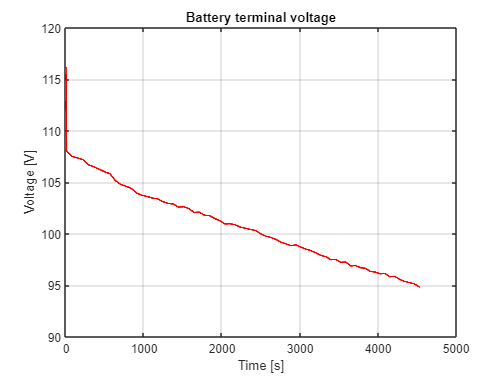

figure()
plot(battery.vHistoric, 'red', 'LineWidth', 1.5)
ylabel('Voltage [V]')
grid on
title('Battery terminal voltage')
xlabel('Time [s]')

# Current / Time

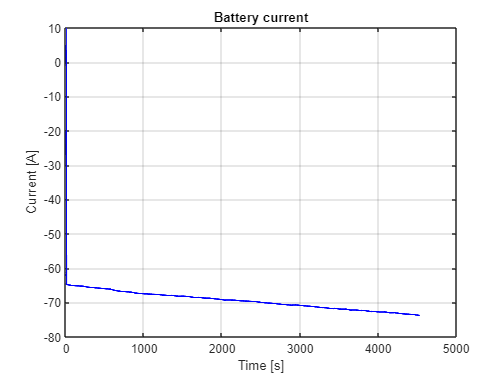

figure()
plot(battery.iHistoric, 'blue', 'LineWidth', 1.5)
ylabel('Current [A]')
grid on
title('Battery current')
xlabel('Time [s]')

# Power / Time

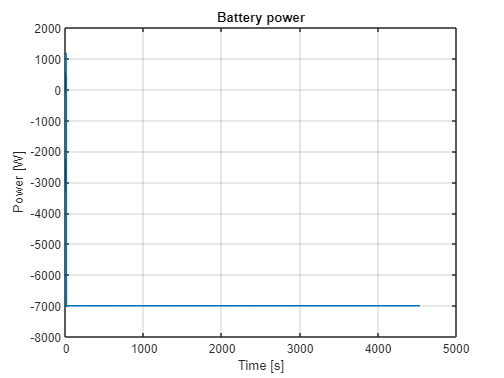

figure()
plot(battery.pHistoric, 'LineWidth', 1.5)
ylabel('Power [W]')
grid on
title('Battery power')
xlabel('Time [s]')

# SoC / Time

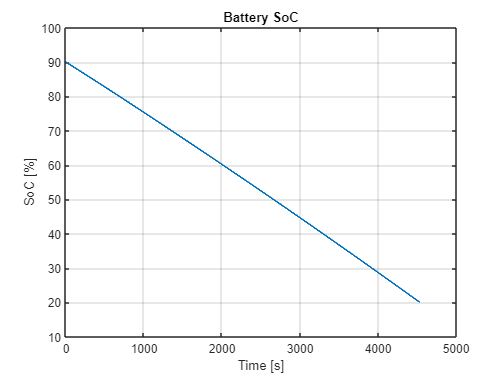

figure()
plot(battery.zHistoric*100, 'LineWidth', 1.5)
ylabel('SoC [%]')
grid on
title('Battery SoC')
xlabel('Time [s]')

# Flow (l/min)

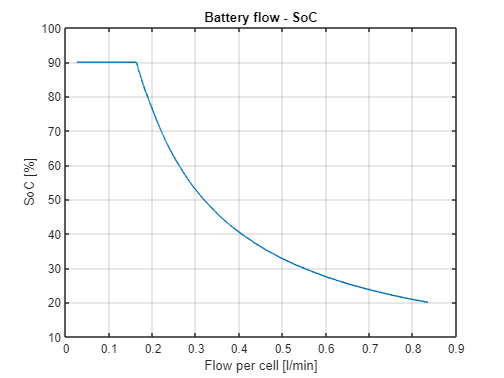

flow.cell = flowRequiredCellConstPower(battery.zHistoric,battery.iHistoric, electrolite.cv, experiment.FF); % (l/min)
flow.stack = flow.cell * nCell;     % (l/min)
flow.tot = nStack .* flow.stack;    % (l/min)

figure()
plot (flow.cell,battery.zHistoric.*100)
ylabel('SoC [%]')
grid on
title('Battery flow - SoC')
xlabel('Flow per cell [l/min]')

# Head (Pa)

##     Head in Stack (Pa)

% Pressure drop in porous electrode
head.Electrode = hElectrode(flow.cell, electrolite.mu, electrode.We, electrode.Le, electrode.He, electrode.df, electrode.ePorosity, electrode.cteCK); % Pa

% Head loss in frames
    % Simulation data for a specific design (losses in the ribs of the frame
    dataFrames = readmatrix("FrameLosses.xlsx");
    head.Frames = hFrames (dataFrames, flow.cell);
    clear dataFrames

% Pressure drop due to Manifold channel
head.Manifold = hChannelRectangular(manifold.W, manifold.H, manifold.L, flow.stack, electrolite.rho, electrolite.mu, manifold.e); % Pa

% Gravity losses
head.Gravity = hGravity(electrolite.rho, electrolite.g, manifold.hManifold); % Pa

% Minor losses
head.MinorLossesStack = hMinorLossesStack(electrolite.rho, flow.cell, manifold.H, manifold.W, frame.HchannelBetweenRibs, frame.WchannelBetweenRibs,frame.numberOfHolesBetweenRibs); % Pa


head.STACK = head.Electrode + 2.*head.Frames + 2.* head.Manifold + head.Gravity + head.MinorLossesStack % Pa

head = struct with fields:
           Electrode: [4.988053546278973e+02 4.987936542409363e+02 4.987819544028704e+02 4.987702551136604e+02 4.987825701701373e+02 3.064219718451554e+03 3.221750050225041e+03 3.232596754051240e+03 3.233988723890143e+03 3.234769300934562e+03 … ]
              Frames: [-15.041893163449277 -15.041925883158118 -15.041958596804124 -15.041991304388041 -15.041956875184422 1.009778267049831e+02 1.151961604476046e+02 1.162053642666072e+02 1.163351582868129e+02 1.164079711235183e+02 … ]
            Manifold: [0.063296298002310 0.063294813272499 0.063293328612340 0.063291844021829 0.063293406750612 0.388836572511034 0.408826507927377 0.410202908945040 0.410379544053136 0.410478595991450 0.410572664564082 0.410666448437560 … ]
             Gravity: 6.110060400000000e+03
    MinorLossesStack: [0.007854012522835 0.007853644066855 0.007853275636802 0.007852907232674 0.007853295027211 0.296393845490774 0.327652181206626 0.329862115973918 0.330146257182419 0.330305649012329

    There are two manifolds, one for the flow input and another one for the flow output. It's the same for the channels of the frames, but in this case, this data of losses are collected in the excel call 'dataFrames'.

    Colectores de división de caudal: el paso de flujo de los manifold a los frames se van a considerar como perdidas por cambio brusco de sección en vez de considerarlos como un giro, ya que se va a suponer que el llenado del manifold es inmediato, e instantes después el flujo se reparte en los frames.

## Head in the hydraulic system

###     Initialitation of the hydraulic system

[pipe, comertialElements] = pipeValues();

-  **Parallel losses:**

h_ab = h1 = h2 = ... = hn

It depends on the path and the flow rate. Linear losses and minor losses in the pipe system are taken into account.

- **    Linear losses**

hL =  f * L/D * rho * velocity ^2 / 2

To calculate linear losses is necessary to use the Colebrook equation, whose procedure is carried out thanks to the use of Matlab *fzero *function.

- **    Minor losses due to comertial elements such as valves, elbows, long radius, tees, etc.**

hMinor = k * rho * 1/2 * velocity ^2 = k * rho * 1/2 * (Q / Apiping) ^2

% LOSSES where flow is flow.stack
    head.pipe_stack = hPipe(pipe.diameter, pipe.LQ, pipe.epsilon, flow.stack, electrolite.rho, electrolite.mu) % Pa

head = struct with fields:
           Electrode: [4.988053546278973e+02 4.987936542409363e+02 4.987819544028704e+02 4.987702551136604e+02 4.987825701701373e+02 3.064219718451554e+03 3.221750050225041e+03 3.232596754051240e+03 3.233988723890143e+03 3.234769300934562e+03 … ]
              Frames: [-15.041893163449277 -15.041925883158118 -15.041958596804124 -15.041991304388041 -15.041956875184422 1.009778267049831e+02 1.151961604476046e+02 1.162053642666072e+02 1.163351582868129e+02 1.164079711235183e+02 … ]
            Manifold: [0.063296298002310 0.063294813272499 0.063293328612340 0.063291844021829 0.063293406750612 0.388836572511034 0.408826507927377 0.410202908945040 0.410379544053136 0.410478595991450 0.410572664564082 0.410666448437560 … ]
             Gravity: 6.110060400000000e+03
    MinorLossesStack: [0.007854012522835 0.007853644066855 0.007853275636802 0.007852907232674 0.007853295027211 0.296393845490774 0.327652181206626 0.329862115973918 0.330146257182419 0.330305649012329

    head.minor_stack = (2 * comertialElements.kValve + 2 * comertialElements.kLongRadius90 + 2 * comertialElements.kT) * electrolite.rho * 1/2 * (flow.stack / 1000 / 60) .^2 / (pipe.area ^ 2) % Pa

head = struct with fields:
           Electrode: [4.988053546278973e+02 4.987936542409363e+02 4.987819544028704e+02 4.987702551136604e+02 4.987825701701373e+02 3.064219718451554e+03 3.221750050225041e+03 3.232596754051240e+03 3.233988723890143e+03 3.234769300934562e+03 … ]
              Frames: [-15.041893163449277 -15.041925883158118 -15.041958596804124 -15.041991304388041 -15.041956875184422 1.009778267049831e+02 1.151961604476046e+02 1.162053642666072e+02 1.163351582868129e+02 1.164079711235183e+02 … ]
            Manifold: [0.063296298002310 0.063294813272499 0.063293328612340 0.063291844021829 0.063293406750612 0.388836572511034 0.408826507927377 0.410202908945040 0.410379544053136 0.410478595991450 0.410572664564082 0.410666448437560 … ]
             Gravity: 6.110060400000000e+03
    MinorLossesStack: [0.007854012522835 0.007853644066855 0.007853275636802 0.007852907232674 0.007853295027211 0.296393845490774 0.327652181206626 0.329862115973918 0.330146257182419 0.330305649012329


% LOSSES where flow is flow.tot
    head.pipe_tot = hPipe(pipe.diameter, pipe.L2Q, pipe.epsilon, flow.tot, electrolite.rho, electrolite.mu) % Pa

head = struct with fields:
           Electrode: [4.988053546278973e+02 4.987936542409363e+02 4.987819544028704e+02 4.987702551136604e+02 4.987825701701373e+02 3.064219718451554e+03 3.221750050225041e+03 3.232596754051240e+03 3.233988723890143e+03 3.234769300934562e+03 … ]
              Frames: [-15.041893163449277 -15.041925883158118 -15.041958596804124 -15.041991304388041 -15.041956875184422 1.009778267049831e+02 1.151961604476046e+02 1.162053642666072e+02 1.163351582868129e+02 1.164079711235183e+02 … ]
            Manifold: [0.063296298002310 0.063294813272499 0.063293328612340 0.063291844021829 0.063293406750612 0.388836572511034 0.408826507927377 0.410202908945040 0.410379544053136 0.410478595991450 0.410572664564082 0.410666448437560 … ]
             Gravity: 6.110060400000000e+03
    MinorLossesStack: [0.007854012522835 0.007853644066855 0.007853275636802 0.007852907232674 0.007853295027211 0.296393845490774 0.327652181206626 0.329862115973918 0.330146257182419 0.330305649012329

    head.minor_tot = (2 * comertialElements.kElbow90 + 5 * comertialElements.kLongRadius90  + 2 * comertialElements.kValve3Way) * electrolite.rho * 1/2 * (flow.tot / 1000 / 60).^2 / (pipe.area ^2) % Pa

head = struct with fields:
           Electrode: [4.988053546278973e+02 4.987936542409363e+02 4.987819544028704e+02 4.987702551136604e+02 4.987825701701373e+02 3.064219718451554e+03 3.221750050225041e+03 3.232596754051240e+03 3.233988723890143e+03 3.234769300934562e+03 … ]
              Frames: [-15.041893163449277 -15.041925883158118 -15.041958596804124 -15.041991304388041 -15.041956875184422 1.009778267049831e+02 1.151961604476046e+02 1.162053642666072e+02 1.163351582868129e+02 1.164079711235183e+02 … ]
            Manifold: [0.063296298002310 0.063294813272499 0.063293328612340 0.063291844021829 0.063293406750612 0.388836572511034 0.408826507927377 0.410202908945040 0.410379544053136 0.410478595991450 0.410572664564082 0.410666448437560 … ]
             Gravity: 6.110060400000000e+03
    MinorLossesStack: [0.007854012522835 0.007853644066855 0.007853275636802 0.007852907232674 0.007853295027211 0.296393845490774 0.327652181206626 0.329862115973918 0.330146257182419 0.330305649012329

 
% TOTAL HEAD IN PIPE
head.PIPE = head.pipe_stack + head.minor_stack + head.pipe_tot + head.minor_tot  % Pa  

head = struct with fields:
           Electrode: [4.988053546278973e+02 4.987936542409363e+02 4.987819544028704e+02 4.987702551136604e+02 4.987825701701373e+02 3.064219718451554e+03 3.221750050225041e+03 3.232596754051240e+03 3.233988723890143e+03 3.234769300934562e+03 … ]
              Frames: [-15.041893163449277 -15.041925883158118 -15.041958596804124 -15.041991304388041 -15.041956875184422 1.009778267049831e+02 1.151961604476046e+02 1.162053642666072e+02 1.163351582868129e+02 1.164079711235183e+02 … ]
            Manifold: [0.063296298002310 0.063294813272499 0.063293328612340 0.063291844021829 0.063293406750612 0.388836572511034 0.408826507927377 0.410202908945040 0.410379544053136 0.410478595991450 0.410572664564082 0.410666448437560 … ]
             Gravity: 6.110060400000000e+03
    MinorLossesStack: [0.007854012522835 0.007853644066855 0.007853275636802 0.007852907232674 0.007853295027211 0.296393845490774 0.327652181206626 0.329862115973918 0.330146257182419 0.330305649012329

**Comertial elements**

- flow.stack     -     2 codos de radio largo + 2 válvulas una a la entrada y otra a la salida del stack + 2T

- flow.tot         -     2 codos +  5 codos de radio largo + 2 kValve3Way

## Global evaluation of the hydraulic system

The battery is an open loop hydraulic system, where all of the fluid starts at the reservoir (tanks) and is returned to the reservoir, that implies that **Hf - Hi = 0.**

**Hf - Hi  = hPump - hStack - hPipe**

Then**:**

**hPump = hStack + hpipe**

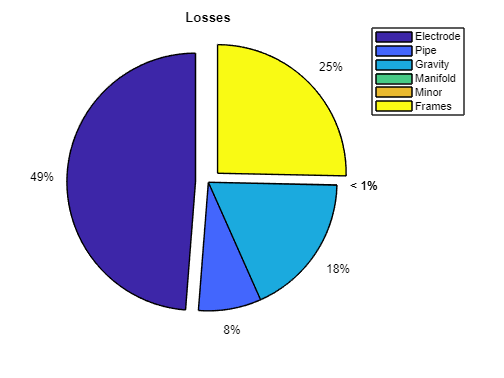

head.PUMP = (head.STACK + head.PIPE) * 10^(-3); % kPa

%............................. PIE ..............................
i = [max(head.Electrode) max(head.PIPE) max(head.Gravity) max(2.*head.Manifold) max(head.MinorLossesStack) max(2.*head.Frames) ];
pie(i, [1 0 0 0 0 1])
% Create legend
lgd = legend({'Electrode','Pipe','Gravity','Manifold', 'Minor','Frames'},'location','bestoutside');
title ('Losses')

% Equation of the hydraulic system:
    ecuInstalation = polyfit (flow.tot, head.PUMP,2); % (head - kPa) (flow - l/min)
%   Valores de caudal y de altura
instalationValues = polyval (ecuInstalation, flow.tot);

# PUMPS

[limitPump,rto] = initPump()

limitPump = struct with fields:
    numMax: 4
     upper: 1.600000000000000


rto = struct with fields:
    Motor: 0.910000000000000
      AFD: 0.900000000000000


La validez de las bombas se ha limitado utilizando el punto de funcionamiento máximo, es decir, caudal y altura maxima que requiere nuestra operación, y un area con respecto a ese punto mayor %.

Se limíta el número de bombas posibles en la instalación porque, depende el caso, puede ser que colocando cierto número de bombas no se alcance el punto de operación requerido.